## Midterm 26 April 2018

### Ex1

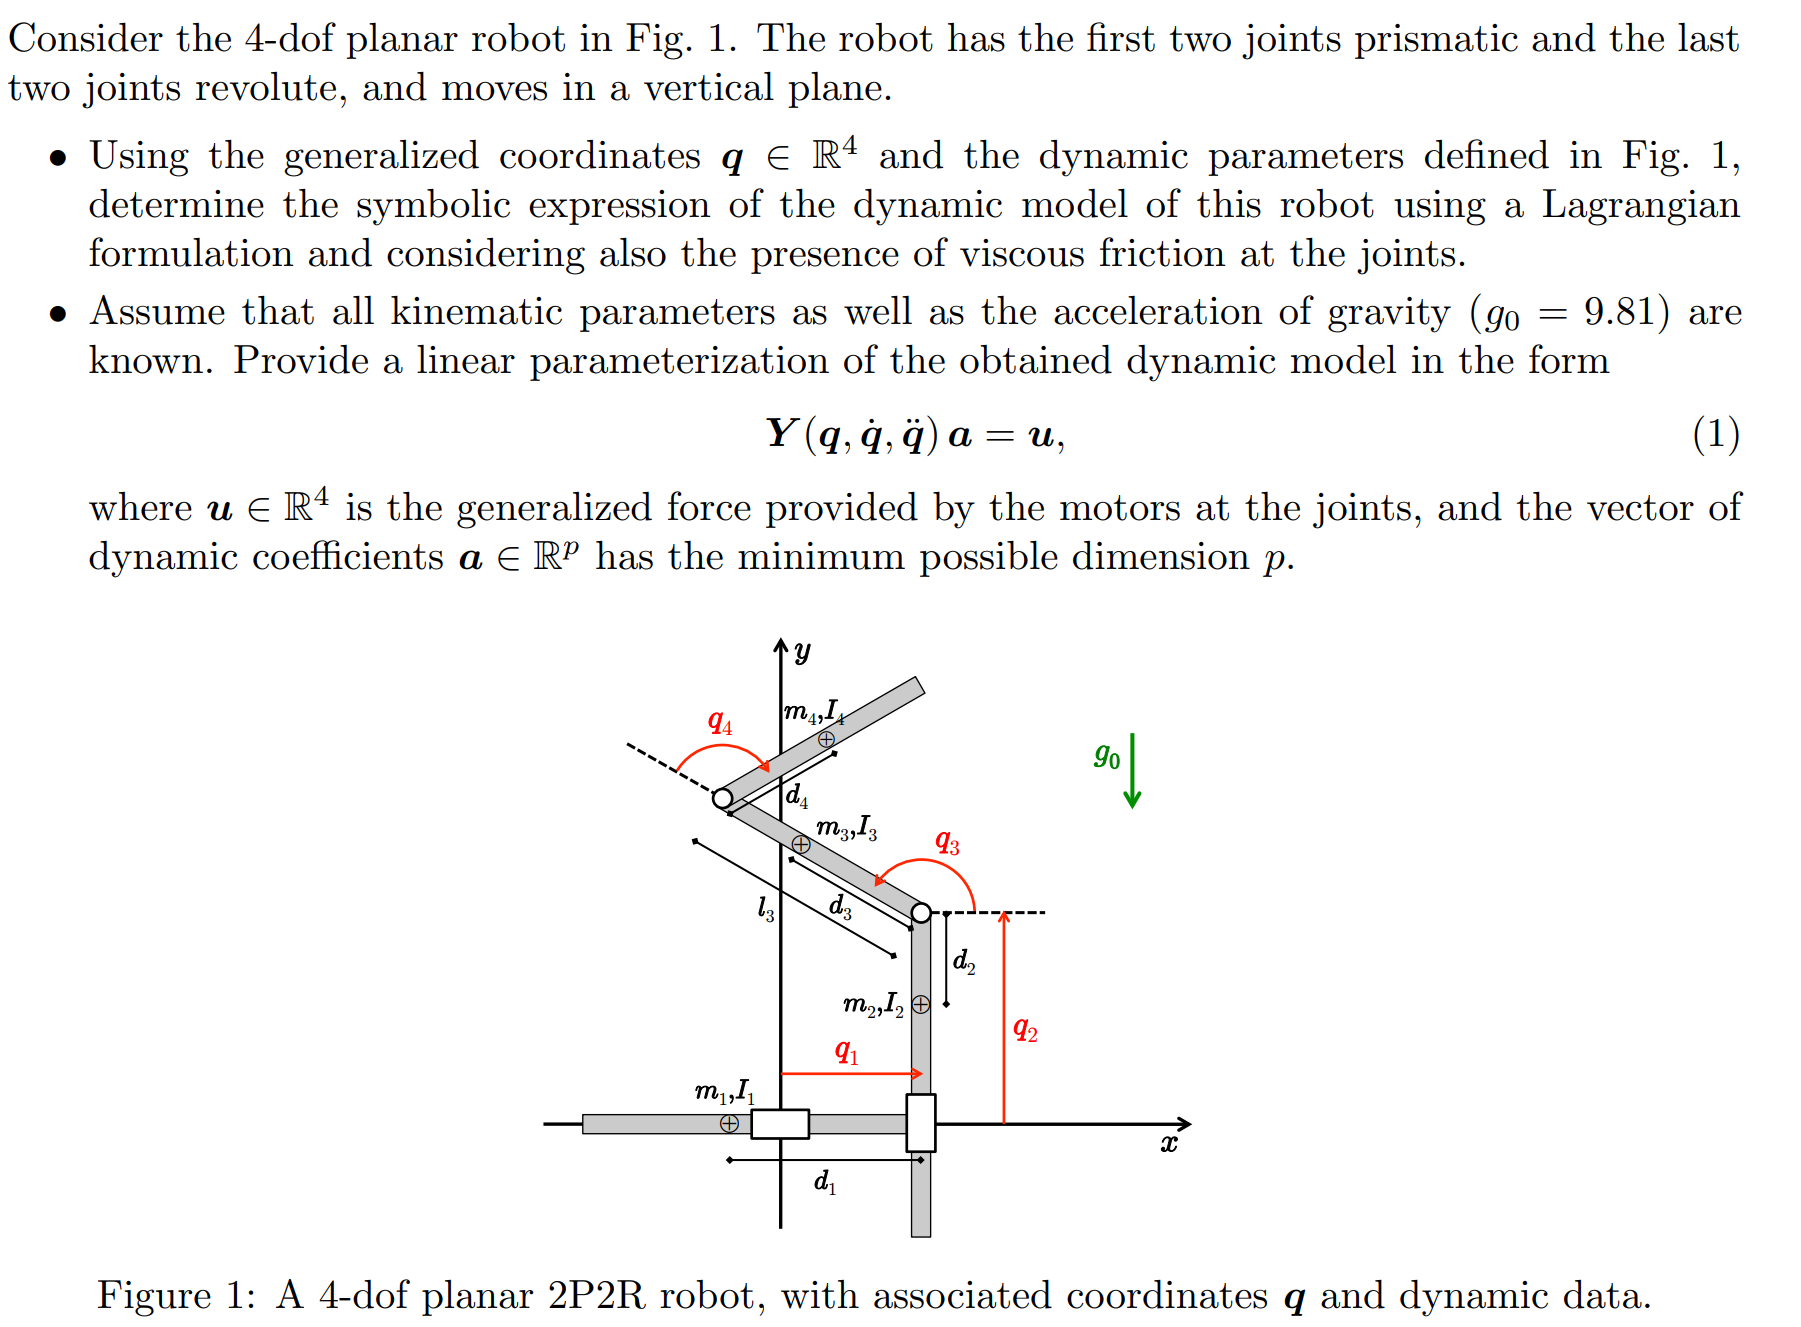

#### Point 1

syms q1 q2 q3 q4 q_dot_1 q_dot_2 q_dot_3 q_dot_4 real
syms m1 m2 m3 m4 I3 I4 d1 d2 d3 d4 l3 l4 l g0 positive 
syms F_v1  F_v2 F_v3 F_v4 real
syms q_ddot_1 q_ddot_2 q_ddot_3 q_ddot_4 real
syms a1 a2 a3 a4 a5 a6 a7 a8 a9 a10 real

% Joint 1
x1 = d1 - q1;
y1 = 0; 

vx1 = diff(x1,q1)*q_dot_1 + diff(x1,q2)*q_dot_2 + diff(x1,q3)*q_dot_3 + diff(x1,q4)*q_dot_4;
vy1 = diff(y1,q1)*q_dot_1 + diff(y1,q2)*q_dot_2 + diff(y1,q3)*q_dot_3 + diff(y1,q4)*q_dot_4;

T1 = 0.5*m1*[vx1 vy1]*[vx1; vy1;]

$$T1 = \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$


% Joint 2
x2 = q1;
y2 = q2 - d2; 

vx2 = diff(x2,q1)*q_dot_1 + diff(x2,q2)*q_dot_2 + diff(x2,q3)*q_dot_3 + diff(x2,q4)*q_dot_4;
vy2 = diff(y2,q1)*q_dot_1 + diff(y2,q2)*q_dot_2 + diff(y2,q3)*q_dot_3 + diff(y2,q4)*q_dot_4;

T2 = 0.5*m2*[vx2 vy2]*[vx2; vy2;]

$$T2 = \frac{m_{2}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{m_{2}\,{{\dot{q}}_{2}}^{2}}{2}$$


% Joint 3
x3 = q1 + d3*cos(q3);
y3 = q2 + d3*sin(q3); 

vx3 = diff(x3,q1)*q_dot_1 + diff(x3,q2)*q_dot_2 + diff(x3,q3)*q_dot_3 + diff(x3,q4)*q_dot_4;
vy3 = diff(y3,q1)*q_dot_1 + diff(y3,q2)*q_dot_2 + diff(y3,q3)*q_dot_3 + diff(y3,q4)*q_dot_4;

T3_tr = 0.5*m3*[vx3 vy3]*[vx3; vy3;];
T3_rot = 0.5*I3*q_dot_3^2;
T3 = T3_rot+T3_tr

$$T3 = \frac{m_{3}\,{\left({\dot{q}}_{2}+d_{3}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)\right)}^{2}}{2}+\frac{m_{3}\,{\left({\dot{q}}_{1}-d_{3}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\right)}^{2}}{2}+\frac{I_{3}\,{{\dot{q}}_{3}}^{2}}{2}$$


% Joint 4
x4 = q1 + l3*cos(q3) + d4*cos(q3+q4);
y4 = q2 + l3*sin(q3) + d4*sin(q3+q4); 

vx4 = diff(x4,q1)*q_dot_1 + diff(x4,q2)*q_dot_2 + diff(x4,q3)*q_dot_3 + diff(x4,q4)*q_dot_4;
vy4 = diff(y4,q1)*q_dot_1 + diff(y4,q2)*q_dot_2 + diff(y4,q3)*q_dot_3 + diff(y4,q4)*q_dot_4

$$vy4 = {\dot{q}}_{2}+{\dot{q}}_{3}\,\left(d_{4}\,\cos\left(q_{3}+q_{4}\right)+l_{3}\,\cos\left(q_{3}\right)\right)+d_{4}\,{\dot{q}}_{4}\,\cos\left(q_{3}+q_{4}\right)$$


T4_tr = 0.5*m4*[vx4 vy4]*[vx4; vy4;];
T4_rot = 0.5*I4*[0 0 q_dot_3+q_dot_4]*[0; 0; q_dot_3+q_dot_4;];
T4 = T4_rot+T4_tr

$$T4 = \frac{m_{4}\,{\left({\dot{q}}_{2}+{\dot{q}}_{3}\,\left(d_{4}\,\cos\left(q_{3}+q_{4}\right)+l_{3}\,\cos\left(q_{3}\right)\right)+d_{4}\,{\dot{q}}_{4}\,\cos\left(q_{3}+q_{4}\right)\right)}^{2}}{2}+\frac{I_{4}\,{\left({\dot{q}}_{3}+{\dot{q}}_{4}\right)}^{2}}{2}+\frac{m_{4}\,{\left({\dot{q}}_{3}\,\left(d_{4}\,\sin\left(q_{3}+q_{4}\right)+l_{3}\,\sin\left(q_{3}\right)\right)-{\dot{q}}_{1}+d_{4}\,{\dot{q}}_{4}\,\sin\left(q_{3}+q_{4}\right)\right)}^{2}}{2}$$


% Total Kinetic Energy
T = T1+T2+T3+T4

$$T = \frac{m_{3}\,{\left({\dot{q}}_{2}+d_{3}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)\right)}^{2}}{2}+\frac{m_{4}\,{\left({\dot{q}}_{2}+{\dot{q}}_{3}\,\left(d_{4}\,\cos\left(q_{3}+q_{4}\right)+l_{3}\,\cos\left(q_{3}\right)\right)+d_{4}\,{\dot{q}}_{4}\,\cos\left(q_{3}+q_{4}\right)\right)}^{2}}{2}+\frac{m_{3}\,{\left({\dot{q}}_{1}-d_{3}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\right)}^{2}}{2}+\frac{I_{4}\,{\left({\dot{q}}_{3}+{\dot{q}}_{4}\right)}^{2}}{2}+\frac{I_{3}\,{{\dot{q}}_{3}}^{2}}{2}+\frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{m_{2}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{m_{2}\,{{\dot{q}}_{2}}^{2}}{2}+\frac{m_{4}\,{\left({\dot{q}}_{3}\,\left(d_{4}\,\sin\left(q_{3}+q_{4}\right)+l_{3}\,\sin\left(q_{3}\right)\right)-{\dot{q}}_{1}+d_{4}\,{\dot{q}}_{4}\,\sin\left(q_{3}+q_{4}\right)\right)}^{2}}{2}$$


% Inertia Matrix
M = sym(zeros(4,4)); 

q_dot = [q_dot_1, q_dot_2, q_dot_3, q_dot_4]; 

for i = 1:4
    for j = 1:4
        M(i,j) = diff(diff(T, q_dot(i)), q_dot(j));
    end
end

M = simplify(M, 'Steps', 100)

$$M = \begin{array}{l} \left(\begin{array}{cccc} m_{1}+m_{2}+m_{3}+m_{4} & 0 & -\frac{m_{4}\,\left(2\,d_{4}\,\sin\left(q_{3}+q_{4}\right)+2\,l_{3}\,\sin\left(q_{3}\right)\right)}{2}-\sigma_{4} & \sigma_{2}\\ 0 & m_{2}+m_{3}+m_{4} & \frac{m_{4}\,\left(2\,d_{4}\,\cos\left(q_{3}+q_{4}\right)+2\,l_{3}\,\cos\left(q_{3}\right)\right)}{2}+\sigma_{5} & \sigma_{3}\\ -m_{4}\,\left(d_{4}\,\sin\left(q_{3}+q_{4}\right)+l_{3}\,\sin\left(q_{3}\right)\right)-\sigma_{4} & m_{4}\,\left(d_{4}\,\cos\left(q_{3}+q_{4}\right)+l_{3}\,\cos\left(q_{3}\right)\right)+\sigma_{5} & m_{3}\,{d_{3}}^{2}+m_{4}\,{d_{4}}^{2}+2\,m_{4}\,\cos\left(q_{4}\right)\,d_{4}\,l_{3}+m_{4}\,{l_{3}}^{2}+I_{3}+I_{4} & \sigma_{1}\\ \sigma_{2} & \sigma_{3} & \sigma_{1} & m_{4}\,{d_{4}}^{2}+I_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{4}\,{d_{4}}^{2}+l_{3}\,m_{4}\,\cos\left(q_{4}\right)\,d_{4}+I_{4}\\ \sigma_{2}=-d_{4}\,m_{4}\,\sin\left(q_{3}+q_{4}\right)\\ \sigma_{3}=d_{4}\,m_{4}\,\cos\left(q_{3}+q_{4}\right)\\ \sigma_{4}=d_{3}\,m_{3}\,\sin\left(q_{3}\right)\\ \sigma_{5}=d_{3}\,m_{3}\,\cos\left(q_{3}\right) \end{array}$$


% Gravity Terms
U1 = 0;
U2 = m2*g0*(y2)

$$U2 = -g_{0}\,m_{2}\,\left(d_{2}-q_{2}\right)$$

U3 = m3*g0*(y3)

$$U3 = g_{0}\,m_{3}\,\left(q_{2}+d_{3}\,\sin\left(q_{3}\right)\right)$$

U4 = m4*g0*(y4)

$$U4 = g_{0}\,m_{4}\,\left(q_{2}+d_{4}\,\sin\left(q_{3}+q_{4}\right)+l_{3}\,\sin\left(q_{3}\right)\right)$$


U = [U1 + U2 + U3 + U4];
g_q = simplify([diff(U, q1); diff(U, q2); diff(U, q3); diff(U, q4)], 'Steps', 100)

$$g\_q = \left(\begin{array}{c} 0\\ g_{0}\,\left(m_{2}+m_{3}+m_{4}\right)\\ g_{0}\,m_{4}\,\left(d_{4}\,\cos\left(q_{3}+q_{4}\right)+l_{3}\,\cos\left(q_{3}\right)\right)+d_{3}\,g_{0}\,m_{3}\,\cos\left(q_{3}\right)\\ d_{4}\,g_{0}\,m_{4}\,\cos\left(q_{3}+q_{4}\right) \end{array}\right)$$



% Coriolis and Centrifugal terms
q  = [q1; q2; q3; q4];
dq = [q_dot_1; q_dot_2; q_dot_3; q_dot_4;];

% Inizializza la matrice C(q, dq) (3x3) a zeri simbolici:
C = sym(zeros(4,4));

for i = 1:4
    for j = 1:4
        % Costruisco ogni elemento C(i,j):
        tmp = 0;
        for k = 1:4
            tmp = tmp + 0.5 * ( ...
                diff(M(i,j), q(k)) + ...
                diff(M(i,k), q(j)) - ...
                diff(M(k,j), q(i)) ) * dq(k);
        end
        C(i,j) = simplify(tmp);  % semplifico
    end
end

c_vec = C * dq;

disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$\left(\begin{array}{cccc} 0 & 0 & -{\dot{q}}_{3}\,\left(\frac{m_{4}\,\left(2\,d_{4}\,\cos\left(q_{3}+q_{4}\right)+2\,l_{3}\,\cos\left(q_{3}\right)\right)}{2}+d_{3}\,m_{3}\,\cos\left(q_{3}\right)\right)-d_{4}\,m_{4}\,{\dot{q}}_{4}\,\cos\left(q_{3}+q_{4}\right) & -d_{4}\,m_{4}\,\cos\left(q_{3}+q_{4}\right)\,\left({\dot{q}}_{3}+{\dot{q}}_{4}\right)\\ 0 & 0 & -{\dot{q}}_{3}\,\left(\frac{m_{4}\,\left(2\,d_{4}\,\sin\left(q_{3}+q_{4}\right)+2\,l_{3}\,\sin\left(q_{3}\right)\right)}{2}+d_{3}\,m_{3}\,\sin\left(q_{3}\right)\right)-d_{4}\,m_{4}\,{\dot{q}}_{4}\,\sin\left(q_{3}+q_{4}\right) & -d_{4}\,m_{4}\,\sin\left(q_{3}+q_{4}\right)\,\left({\dot{q}}_{3}+{\dot{q}}_{4}\right)\\ 0 & 0 & -d_{4}\,l_{3}\,m_{4}\,{\dot{q}}_{4}\,\sin\left(q_{4}\right) & -d_{4}\,l_{3}\,m_{4}\,\sin\left(q_{4}\right)\,\left({\dot{q}}_{3}+{\dot{q}}_{4}\right)\\ 0 & 0 & d_{4}\,l_{3}\,m_{4}\,{\dot{q}}_{3}\,\sin\left(q_{4}\right) & 0 \end{array}\right)$$


disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$\left(\begin{array}{c} -{\dot{q}}_{3}\,\left({\dot{q}}_{3}\,\left(\frac{m_{4}\,\left(2\,d_{4}\,\cos\left(q_{3}+q_{4}\right)+2\,l_{3}\,\cos\left(q_{3}\right)\right)}{2}+d_{3}\,m_{3}\,\cos\left(q_{3}\right)\right)+d_{4}\,m_{4}\,{\dot{q}}_{4}\,\cos\left(q_{3}+q_{4}\right)\right)-d_{4}\,m_{4}\,{\dot{q}}_{4}\,\cos\left(q_{3}+q_{4}\right)\,\left({\dot{q}}_{3}+{\dot{q}}_{4}\right)\\ -{\dot{q}}_{3}\,\left({\dot{q}}_{3}\,\left(\frac{m_{4}\,\left(2\,d_{4}\,\sin\left(q_{3}+q_{4}\right)+2\,l_{3}\,\sin\left(q_{3}\right)\right)}{2}+d_{3}\,m_{3}\,\sin\left(q_{3}\right)\right)+d_{4}\,m_{4}\,{\dot{q}}_{4}\,\sin\left(q_{3}+q_{4}\right)\right)-d_{4}\,m_{4}\,{\dot{q}}_{4}\,\sin\left(q_{3}+q_{4}\right)\,\left({\dot{q}}_{3}+{\dot{q}}_{4}\right)\\ -d_{4}\,l_{3}\,m_{4}\,{\dot{q}}_{4}\,\sin\left(q_{4}\right)\,\left({\dot{q}}_{3}+{\dot{q}}_{4}\right)-d_{4}\,l_{3}\,m_{4}\,{\dot{q}}_{3}\,{\dot{q}}_{4}\,\sin\left(q_{4}\right)\\ d_{4}\,l_{3}\,m_{4}\,{{\dot{q}}_{3}}^{2}\,\sin\left(q_{4}\right) \end{array}\right)$$


disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$\left(\begin{array}{cccc} 0 & 0 & -{\dot{q}}_{3}\,\left(\frac{m_{4}\,\left(2\,d_{4}\,\cos\left(q_{3}+q_{4}\right)+2\,l_{3}\,\cos\left(q_{3}\right)\right)}{2}+d_{3}\,m_{3}\,\cos\left(q_{3}\right)\right)-d_{4}\,m_{4}\,{\dot{q}}_{4}\,\cos\left(q_{3}+q_{4}\right) & -d_{4}\,m_{4}\,\cos\left(q_{3}+q_{4}\right)\,\left({\dot{q}}_{3}+{\dot{q}}_{4}\right)\\ 0 & 0 & -{\dot{q}}_{3}\,\left(\frac{m_{4}\,\left(2\,d_{4}\,\sin\left(q_{3}+q_{4}\right)+2\,l_{3}\,\sin\left(q_{3}\right)\right)}{2}+d_{3}\,m_{3}\,\sin\left(q_{3}\right)\right)-d_{4}\,m_{4}\,{\dot{q}}_{4}\,\sin\left(q_{3}+q_{4}\right) & -d_{4}\,m_{4}\,\sin\left(q_{3}+q_{4}\right)\,\left({\dot{q}}_{3}+{\dot{q}}_{4}\right)\\ 0 & 0 & -d_{4}\,l_{3}\,m_{4}\,{\dot{q}}_{4}\,\sin\left(q_{4}\right) & -d_{4}\,l_{3}\,m_{4}\,\sin\left(q_{4}\right)\,\left({\dot{q}}_{3}+{\dot{q}}_{4}\right)\\ 0 & 0 & d_{4}\,l_{3}\,m_{4}\,{\dot{q}}_{3}\,\sin\left(q_{4}\right) & 0 \end{array}\right)$$


disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$\left(\begin{array}{c} -{\dot{q}}_{3}\,\left({\dot{q}}_{3}\,\left(\frac{m_{4}\,\left(2\,d_{4}\,\cos\left(q_{3}+q_{4}\right)+2\,l_{3}\,\cos\left(q_{3}\right)\right)}{2}+d_{3}\,m_{3}\,\cos\left(q_{3}\right)\right)+d_{4}\,m_{4}\,{\dot{q}}_{4}\,\cos\left(q_{3}+q_{4}\right)\right)-d_{4}\,m_{4}\,{\dot{q}}_{4}\,\cos\left(q_{3}+q_{4}\right)\,\left({\dot{q}}_{3}+{\dot{q}}_{4}\right)\\ -{\dot{q}}_{3}\,\left({\dot{q}}_{3}\,\left(\frac{m_{4}\,\left(2\,d_{4}\,\sin\left(q_{3}+q_{4}\right)+2\,l_{3}\,\sin\left(q_{3}\right)\right)}{2}+d_{3}\,m_{3}\,\sin\left(q_{3}\right)\right)+d_{4}\,m_{4}\,{\dot{q}}_{4}\,\sin\left(q_{3}+q_{4}\right)\right)-d_{4}\,m_{4}\,{\dot{q}}_{4}\,\sin\left(q_{3}+q_{4}\right)\,\left({\dot{q}}_{3}+{\dot{q}}_{4}\right)\\ -d_{4}\,l_{3}\,m_{4}\,{\dot{q}}_{4}\,\sin\left(q_{4}\right)\,\left({\dot{q}}_{3}+{\dot{q}}_{4}\right)-d_{4}\,l_{3}\,m_{4}\,{\dot{q}}_{3}\,{\dot{q}}_{4}\,\sin\left(q_{4}\right)\\ d_{4}\,l_{3}\,m_{4}\,{{\dot{q}}_{3}}^{2}\,\sin\left(q_{4}\right) \end{array}\right)$$

#### Point 2

% Linear Parametrization
% a1 = m1+m2+m3+m4
% a2 = m1+m2+m3
% a3 = I3 + m3*d3^2 + m4*l3^2 + I4 + m4*d4^2
% a4 = I4 + m4*d4^2
% a5 = m4*d4
% a6 = m3*d3 + m4*l3
% a7 = F_v1
% a8 = F_v2
% a9 = F_v3
% a10 = F_v4

params = [a1, a2, a3, a4, a5, a6, a7, a8, a9, a10];

q_dot_dot = [q_ddot_1; q_ddot_2; q_ddot_3; q_ddot_4;];

M_param = [a1 0 -a6*sin(q3)-a5*sin(q3 + q4)  -a5*sin(q3 + q4);
            0 a2  a6*cos(q3)+a5*cos(q3 + q4)  a5*cos(q3 + q4);
    -a6*sin(q3)-a5*sin(q3 + q4) a6*cos(q3)+a5*cos(q3 + q4) a3+2*a5*l3*cos(q4) a4+a5*l3*cos(q4);
 -a5*sin(q3 + q4) a5*cos(q3+q4) a4+a5*l3*cos(q4) a4;];

c_param =[ -a5*cos(q3+q4)*(q_dot_3+q_dot_4)^2-a6*cos(q3)*q_dot_3^2;
           -a5*sin(q3+q4)*(q_dot_3 + q_dot_4)^2-a6*sin(q3)*q_dot_3^2;
           -a5*l3*sin(q4)*q_dot_4*(2*q_dot_3+q_dot_4);
            a5*l3*sin(q4)*q_dot_3^2;];
g_param = [ 0;
          a2*g0;
          a6*g0*cos(q3)+a5*g0*cos(q3 + q4);
          a5*g0*cos(q3+q4);];

F_param = [a7*q_dot_1;
           a8*q_dot_2;
           a9*q_dot_3;
           a10*q_dot_4;]

$$F\_param = \left(\begin{array}{c} a_{7}\,{\dot{q}}_{1}\\ a_{8}\,{\dot{q}}_{2}\\ a_{9}\,{\dot{q}}_{3}\\ a_{10}\,{\dot{q}}_{4} \end{array}\right)$$


Ya = M_param*q_dot_dot + c_param + g_param + F_param;

Y = extract_Y_v3(Ya,params)

$$Y = \begin{array}{l} \left(\begin{array}{cccccccccc} {\ddot{q}}_{1} & 0 & 0 & 0 & -{\ddot{q}}_{3}\,\sin\left(q_{3}+q_{4}\right)-{\ddot{q}}_{4}\,\sin\left(q_{3}+q_{4}\right)-\cos\left(q_{3}+q_{4}\right)\,{\left({\dot{q}}_{3}+{\dot{q}}_{4}\right)}^{2} & -\cos\left(q_{3}\right)\,{{\dot{q}}_{3}}^{2}-{\ddot{q}}_{3}\,\sin\left(q_{3}\right) & {\dot{q}}_{1} & 0 & 0 & 0\\ 0 & g_{0}+{\ddot{q}}_{2} & 0 & 0 & {\ddot{q}}_{3}\,\cos\left(q_{3}+q_{4}\right)+{\ddot{q}}_{4}\,\cos\left(q_{3}+q_{4}\right)-\sin\left(q_{3}+q_{4}\right)\,{\left({\dot{q}}_{3}+{\dot{q}}_{4}\right)}^{2} & {\ddot{q}}_{3}\,\cos\left(q_{3}\right)-{{\dot{q}}_{3}}^{2}\,\sin\left(q_{3}\right) & 0 & {\dot{q}}_{2} & 0 & 0\\ 0 & 0 & {\ddot{q}}_{3} & {\ddot{q}}_{4} & \sigma_{1}+\sigma_{3}-\sigma_{2}+2\,l_{3}\,{\ddot{q}}_{3}\,\cos\left(q_{4}\right)+l_{3}\,{\ddot{q}}_{4}\,\cos\left(q_{4}\right)-l_{3}\,{\dot{q}}_{4}\,\sin\left(q_{4}\right)\,\left(2\,{\dot{q}}_{3}+{\dot{q}}_{4}\right) & g_{0}\,\cos\left(q_{3}\right)+{\ddot{q}}_{2}\,\cos\left(q_{3}\right)-{\ddot{q}}_{1}\,\sin\left(q_{3}\right) & 0 & 0 & {\dot{q}}_{3} & 0\\ 0 & 0 & 0 & {\ddot{q}}_{3}+{\ddot{q}}_{4} & l_{3}\,\sin\left(q_{4}\right)\,{{\dot{q}}_{3}}^{2}+\sigma_{1}+\sigma_{3}-\sigma_{2}+l_{3}\,{\ddot{q}}_{3}\,\cos\left(q_{4}\right) & 0 & 0 & 0 & 0 & {\dot{q}}_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=g_{0}\,\cos\left(q_{3}+q_{4}\right)\\ \sigma_{2}={\ddot{q}}_{1}\,\sin\left(q_{3}+q_{4}\right)\\ \sigma_{3}={\ddot{q}}_{2}\,\cos\left(q_{3}+q_{4}\right) \end{array}$$

### Ex 2

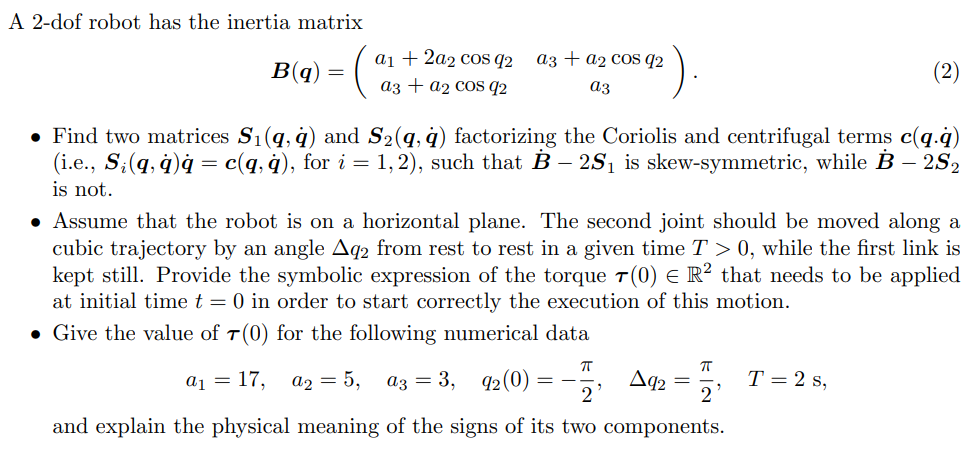

B_q = [a1+2*a2*cos(q2) a3+a2*cos(q2);
       a3+a2*cos(q2) a3;];
b_11 = diff(a1+2*a2*cos(q2), q1)*q_dot_1 + diff(a1+2*a2*cos(q2), q2)*q_dot_2;
b_12 = diff(a3+a2*cos(q2), q1)*q_dot_1 + diff(a3+a2*cos(q2), q2)*q_dot_2;
b_21 = diff(a3+a2*cos(q2), q1)*q_dot_1 + diff(a3+a2*cos(q2), q2)*q_dot_2;
b_22 = diff(a3, q1)*q_dot_1 + diff(a3, q2)*q_dot_2;

B_dot_q = [b_11 b_12;
           b_21 b_22;]

$$B\_dot\_q = \left(\begin{array}{cc} -2\,a_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right) & -a_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\\ -a_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right) & 0 \end{array}\right)$$


q = [q1; q2];
n = length(q);    
cell_c_k = cell(1, n);
for i=1:n
    M_k = B_q(:, i);
    c_k = 0.5*(jacobian(M_k, q)+(jacobian(M_k, q)') - diff(B_q, q(i)));
    c_k = simplify(c_k)
    cell_c_k{i} = c_k;
end

$$c\_k = \left(\begin{array}{cc} 0 & -a_{2}\,\sin\left(q_{2}\right)\\ -a_{2}\,\sin\left(q_{2}\right) & -a_{2}\,\sin\left(q_{2}\right) \end{array}\right)$$

$$c\_k = \left(\begin{array}{cc} a_{2}\,\sin\left(q_{2}\right) & 0\\ 0 & 0 \end{array}\right)$$

### Ex3

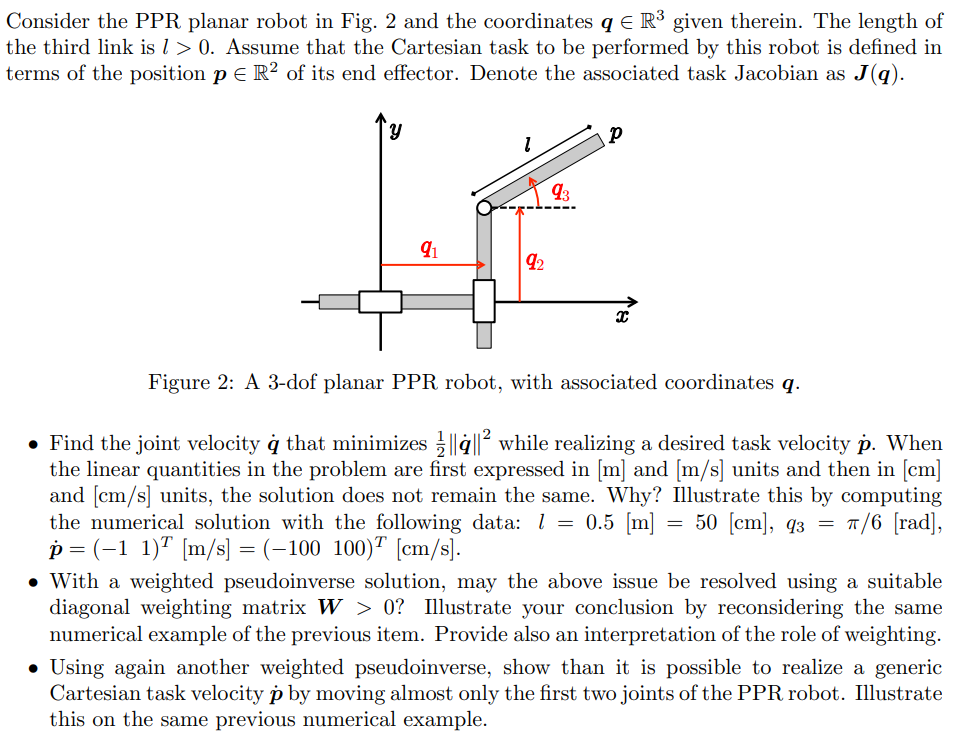

p = [q1+l*cos(q3);
     q2+l*sin(q3);];
J = jacobian(p,[q1,q2,q3])

$$J = \left(\begin{array}{ccc} 1 & 0 & -l\,\sin\left(q_{3}\right)\\ 0 & 1 & l\,\cos\left(q_{3}\right) \end{array}\right)$$

J_pinv = pinv(J);
p_dot = [-1;1;];
p_dot_2 = [-100;100;];
q_dot = eval(subs(J_pinv*p_dot,[q3,l],[pi/6,0.5]))

q_dot =    -0.8634
    0.7634
    0.5464


q_dot_2 = eval(subs(J_pinv*p_dot_2,[q3,l],[pi/6,50]))

q_dot_2 =   -31.7260
  -18.2540
    2.7310


#### Utils function


function Y = extract_Y_v3(Ya, dynamic_symbols)
    % M: inertia matrix
    % C: christoffel matrix
    % G: potential enrgy matrix
    % joint_acceleration: array with joint acceleration
    % this four items are use to build dynamic model

    % dynamic_model: in the form M*ddq + C + G
    % dynamic_coefficient: an array which contain symbol like [ m1+m3 I2
    % ...]
    % dynamic_symbols: how substitute coefficient, so [a1 a2 ... a_n]
    
    Y = sym([]);
    Y_columns = length(dynamic_symbols);
    dynamic_symbols = reshape(dynamic_symbols, 1, Y_columns);

    for i=1:Y_columns
        
        subs_array = zeros(1, Y_columns);
        subs_array(i) = 1;

        Yi = subs(Ya, dynamic_symbols, subs_array);

        Y = [Y, Yi];
    end
    
end